%run eerst
addpath('../Code/hulpFuncties/')

% data generation
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100);
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [[data_XA data_XB]; [data_YA data_YB]; [ones(1,length(data_XA)) zeros(1,length(data_XB))]; [zeros(1,length(data_XA)) ones(1,length(data_XB))]]

data =     0.2780    0.6710    0.5750    0.2740    0.4320    0.2520    0.5770    0.6300    0.5450    0.2860    0.3600    0.3400    0.5050    0.3760    0.6020    0.3630    0.2040    0.2770    0.7310    0.3400    0.3950    0.3360    0.7540    0.3130    0.4570    0.6590    0.6410    0.6580    0.2110    0.4610    0.6960    0.5000    0.7160    0.5260    0.4920    0.3540    0.5010    0.5240    0.5830    0.4110    0.5950    0.7170    0.4870    0.3100    0.5770    0.4420    0.3600    0.2080    0.4510    0.7700
    0.3820    0.5780    0.3120    0.6440    0.5260    0.4150    0.5210    0.7470    0.2680    0.3510    0.3040    0.7480    0.7140    0.3490    0.6900    0.4800    0.5180    0.5590    0.3400    0.7270    0.6060    0.2610    0.4640    0.2730    0.7670    0.2570    0.6430    0.5430    0.4930    0.4060    0.3430    0.2760    0.5730    0.6690    0.7460    0.4690    0.5700    0.2340    0.3910    0.3340    0.5550    0.5120    0.5900    0.6450    0.4980    0.3530    0.3880    0.5180    0.6580  

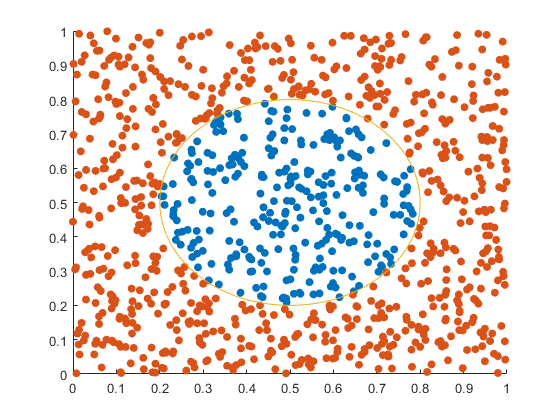


th = 0:pi/50:2*pi;
xunit = 0.3 * cos(th) + 0.5;
yunit = 0.3 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(data_XA,data_YA,'filled')
scatter(data_XB,data_YB,'filled')
plot(xunit, yunit);

%parameters
step = 0.1;
batch_size = 15;
max_iterations = 10^7;
model_params = [0, 10];

%rng set werkt enkel in de cell zelf
rng(5000);
network = NN_gen([2 5 2],'normal',model_params);
trained_network = train_net(network, data, step, max_iterations, batch_size, model_params, [0, 1]);

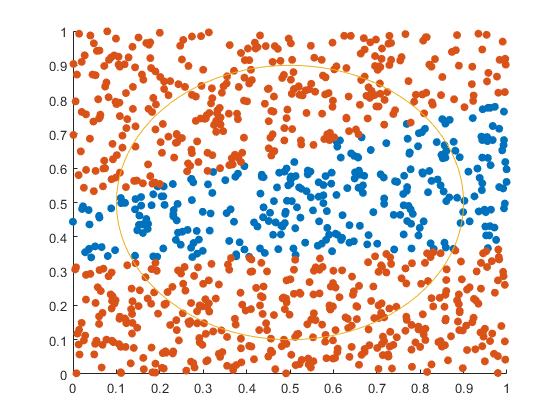

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    % Forward pass
    a2 = sigmoid_activate(x,trained_network{1,1},trained_network{1,2});
    a3 = sigmoid_activate(a2,trained_network{1,3},trained_network{1,4});
    if a3(1) >= a3(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);